clear all
close all
clc


## MN1 - **Compute the Thévenin between 1 and 2 terminals**

## 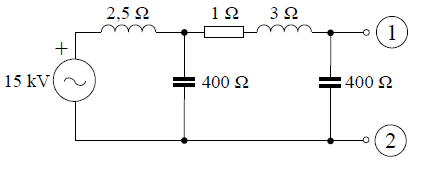

**Solution of the exercise**

## Resolution method 1

disp('Solution method 1')

Solution method 1


z1=2.5*1i

z1 = 0.0000 + 2.5000i

z2=1+3*1i

z2 = 1.0000 + 3.0000i

z3=-1i*400

z3 = 0.0000e+00 - 4.0000e+02i

z4=z3

z4 = 0.0000e+00 - 4.0000e+02i

Matrix (A) and independent vector (B) definition Ax=B

A=[1/z1, -1/z1         ,          0, 1; 
  -1/z1, 1/z1+1/z2+1/z3,      -1/z2, 0;
    0,            -1/z2,  1/z2+1/z4, 0;
    1,                0,          0, 0]

A =    0.0000 - 0.4000i   0.0000 + 0.4000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.4000i   0.1000 - 0.6975i  -0.1000 + 0.3000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1000 + 0.3000i   0.1000 - 0.2975i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



B=[0;0;0;15e3]

B =            0
           0
           0
       15000


Solving the system of equations

sol1=inv(A)*B

sol1 = 	1.0e+04 *

   1.5000 + 0.0000i
   1.5191 - 0.0000i
   1.5305 - 0.0039i
  -0.0000 - 0.0076i


sol1m=abs(sol1)

sol1m = 	1.0e+04 *

    1.5000
    1.5191
    1.5305
    0.0076


sol1a=angle(sol1)*180/pi

sol1a =          0
   -0.0009
   -0.1452
  -90.0734


Computing the Thévenin

uth=sol1(3)

uth = 1.5305e+04 - 3.8798e+01i

uthm=abs(sol1(3))

uthm = 1.5305e+04

utha=angle(sol1(3))*180/pi

utha = -0.1452


Z=inv(A);
Zth=Z(3,3)

Zth = 1.0282 + 5.5902i

## Resolution method 2

Matrix (A) and independent vector (B) definition Ax=B

disp(' ')

disp('Solution method 2')

Solution method 2


A=[1/z1+1/z2+1/z3,-1/z2;
    -1/z2, 1/z2+1/z4]

A =    0.1000 - 0.6975i  -0.1000 + 0.3000i
  -0.1000 + 0.3000i   0.1000 - 0.2975i



B=[15000/z1;0]

B = 	1.0e+03 *

   0.0000 - 6.0000i
   0.0000 + 0.0000i


Solving the system of equations

sol2=inv(A)*B;

sol2m=abs(sol2)

sol2m = 	1.0e+04 *

    1.5191
    1.5305


sol2a=angle(sol2)*180/pi

sol2a =    -0.0009
   -0.1452


Computing the Thévenin

uth=sol2(2)

uth = 1.5305e+04 - 3.8798e+01i

uthm=abs(sol2(2))

uthm = 1.5305e+04

utha=angle(sol2(2))*180/pi

utha = -0.1452


Z=inv(A);
Zth=Z(2,2)

Zth = 1.0282 + 5.5902i